Error absoluto por definicion es


$$\textrm{Error absoluto}=V_{real}-V_{calculado}$$


El error relativo es


$$\textrm{Error relativo} =\frac{V_{real}-V_{calulado}}{V_{real}}$$


El primero por default en Matlab son


$$\textrm{Error Absoluto} = 10^{-6}, \;\;\; \textrm{Error Realativo} =10^{-3}$$


Para cambiar el error especifiacamente para el algoritmo ode45 se hace lo siguiente

La cuarta entrada del algoritmo ode45 representa las opciones, RelTol es Relative Tolerance y AbsTol Es Absolute Tolerence. b representa alguna variable que no conozcoamos

Se resuelve la siguiente ecuación


$$\frac{d^2y}{dt^2}+4\frac{dy}{dt}+\exp(-2y)=4 $$


Con las condiciones


$$y(0) = 0,\;\;\; y\prime(0)=0$$


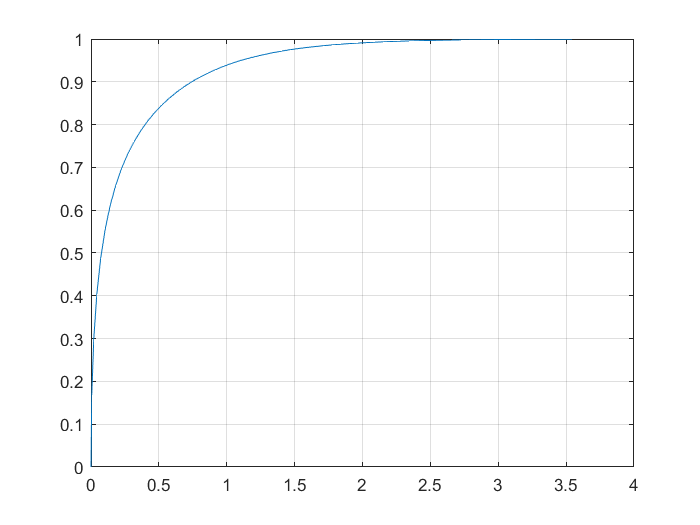

f=@(t,y) [y(2);4-exp(-2*y(1))-4*y(2)];
rvt=linspace(0,4,2^6);
ci=[0;0];
[t,y]=ode45(f,rvt,ci);
plot(y(:,1),y(:,2)),grid

Se repite cambiando el error relativo

f=@(t,y) [y(2);4-exp(-2*y(1))-4*y(2)];
a=odeset('RelTol',1e-10,'AbsTol',1e-6);
rvt=linspace(0,4,2^6);
ci=[0;0];
[t,y]=ode45(f,rvt,ci);
plot(y(:,1),y(:,2)),grid

Resolvemos el siguiente sistema


$$\frac{d^2y}{dt^2}+700\frac{dy}{dt}+699y=0$$


Con las condiciones iniciales


$$y(0)=1 \;\;\; y\prime(0)=0$$


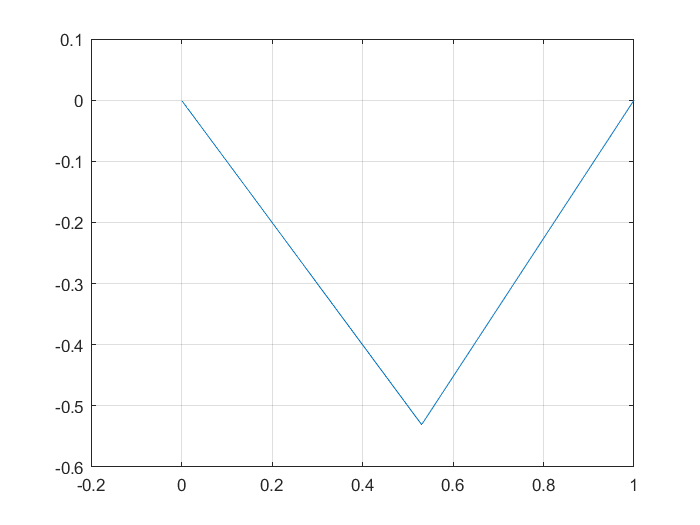

f=@(t,y) [y(2);-699*y(1)-700*y(2)];
rvt=linspace(0,40,2^6);
ci=[1;0];
[t,y]=ode45(f,rvt,ci);
plot(y(:,1),y(:,2)),grid

Ahora reducimos el error

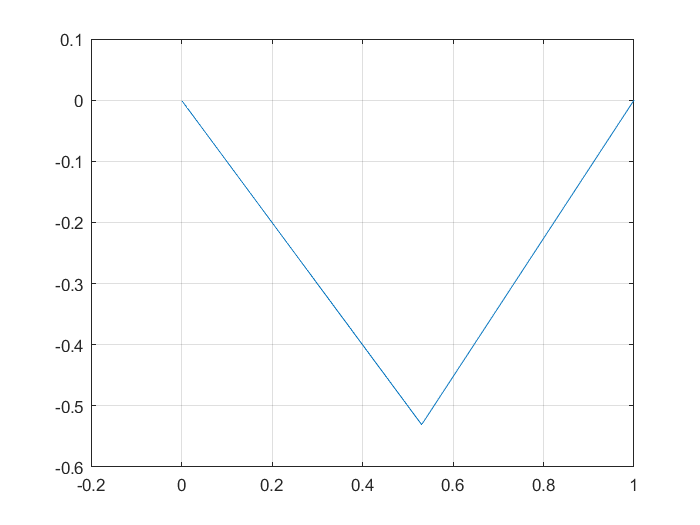

f=@(t,y) [y(2);-699*y(1)-700*y(2)];
rvt=linspace(0,40,2^6);
a=odeset('RelTol',1e-10,'AbsTol',1e-6);
ci=[1;0];
[t,y]=ode45(f,rvt,ci,a);
plot(y(:,1),y(:,2)),grid

Resolvemos el siguiente sistema


$$\frac{d^2y}{dt^2}+2000\frac{dy}{dt}+1999y=0$$


Con las condiciones iniciales


$$y(0)=1 \;\;\; y\prime(0)=0$$


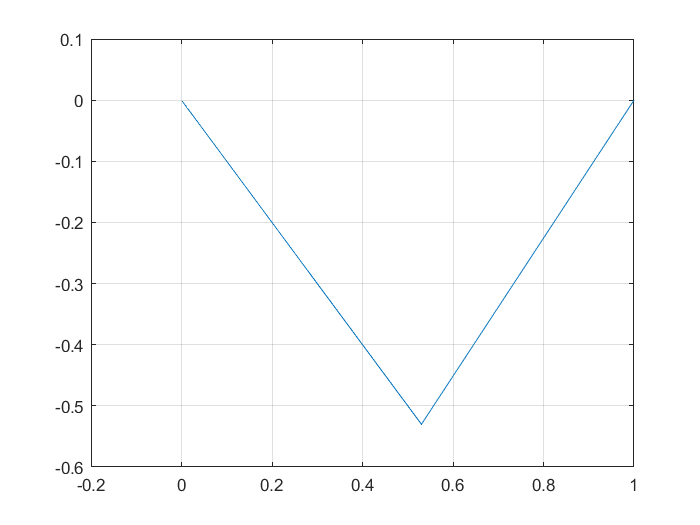

f=@(t,y) [y(2);-1999*y(1)-2000*y(2)];
rvt=linspace(0,40,2^6);
ci=[1;0];
[t,y]=ode45(f,rvt,ci);
plot(y(:,1),y(:,2)),grid

Ahora reducimos el error

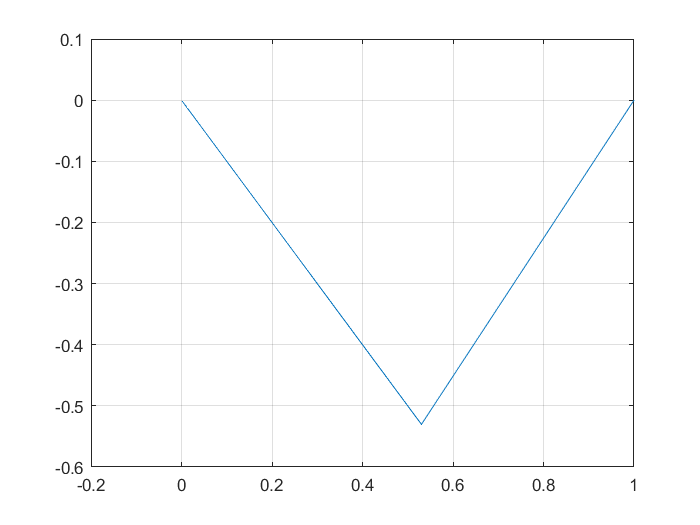

f=@(t,y) [y(2);-1999*y(1)-2000*y(2)];
rvt=linspace(0,40,2^6);
a=odeset('RelTol',1e-10,'AbsTol',1e-6);
ci=[1;0];
[t,y]=ode45(f,rvt,ci,a);
plot(y(:,1),y(:,2)),grid